## Loads

clear
load("modelo8.mat")

s = tf("s");

An, Bn

An =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
         0   -4.4814         0  -11.3179    0.3395         0
         0  114.5125         0  129.1583   -3.8747         0
         0         0         0         0         0   -7.7192


Bn =          0         0
         0         0
         0         0
    1.5267         0
  -17.4221         0
         0  -17.3540


## Simulink

global odeFuncSimulink
odeFuncSimulink = odeFunction(fn, [States; Inputs])

odeFuncSimulink = function_handle with value:
    @(t,in2)[in2(4,:);in2(5,:);in2(6,:);((in2(5,:).*1.191647389643175e-6-in2(4,:).*3.97215796547725e-5+in2(7,:).*5.358018433704305e-6-cos(in2(2,:)).*sin(in2(2,:)).*1.950880702464e-5+in2(5,:).*cos(in2(2,:)).*2.864490655182691e-7-in2(4,:).*cos(in2(2,:)).*9.548302183942302e-6+in2(7,:).*cos(in2(2,:)).*1.287964364881323e-6+in2(5,:).^2.*sin(in2(2,:)).*2.481894498518069e-7-in2(6,:).^2.*cos(in2(2,:)).^2.*sin(in2(2,:)).*2.036413386859035e-7).*(-1.501501501501502e+2))./(cos(in2(2,:)).^2.*2.985984e-4-9.522452360641909e-4);((in2(5,:).*1.463919267691157e-5-in2(4,:).*4.879730892303856e-4+in2(7,:).*6.582237740723648e-5-sin(in2(2,:)).*9.970121020072811e-4-in2(6,:).^2.*sin(in2(2,:).*2.0).*5.203621084630516e-6+in2(5,:).^2.*sin(in2(2,:).*2.0).*1.988665344e-6+in2(5,:).*cos(in2(2,:)).*1.90966043678846e-5-in2(4,:).*cos(in2(2,:)).*6.365534789294868e-4+in2(7,:).*cos(in2(2,:)).*8.586429099208817e-5).*1.501501501501502e+2)./(cos(in2(2,:).*2.0).*2.985984e-4-1.6058920

## Controle LQR 

desired_states = [2 4 5];
q_fo, q_fo(desired_states)

$$q\_fo = \left(\begin{array}{c} x\left(t\right)\\ \theta \left(t\right)\\ \text{psi}\left(t\right)\\ \mathrm{Dxt}\left(t\right)\\ \mathrm{Dthetat}\left(t\right)\\ {\mathrm{Dpsi}}_{t}\left(t\right) \end{array}\right)$$

$$ans = \left(\begin{array}{c} \theta \left(t\right)\\ \mathrm{Dxt}\left(t\right)\\ \mathrm{Dthetat}\left(t\right) \end{array}\right)$$

Ar = An(desired_states,desired_states)

Ar =          0         0    1.0000
   -4.4814  -11.3179    0.3395
  114.5125  129.1583   -3.8747


Br = Bn(desired_states,1)

Br =          0
    1.5267
  -17.4221


Cr = Cn(desired_states,desired_states)

Cr =      1     0     0
     0     1     0
     0     0     1


rank(obsv(Ar, Cr)), rank(ctrb(Ar, Br)) 

ans = 3

ans = 3

Q = Cr'*Cr

Q =      1     0     0
     0     1     0
     0     0     1


R = 0.08;

Kr = lqr(Ar, Br, Q, R)

Kr =   -29.2124  -15.6269   -4.5851


sys_mf = ss(Ar - Br*Kr, Br, Cr, 0)

sys_mf =
 
  A = 
           x1      x2      x3
   x1       0       0       1
   x2   40.12   12.54   7.339
   x3  -394.4  -143.1  -83.76
 
  B = 
           u1
   x1       0
   x2   1.527
   x3  -17.42
 
  C = 
       x1  x2  x3
   y1   1   0   0
   y2   0   1   0
   y3   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
 
Continuous-time state-space model.


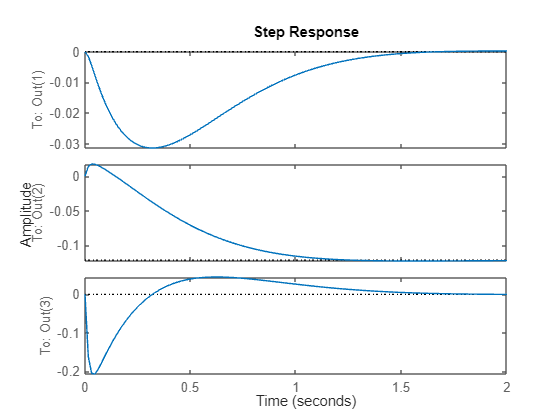

figure
step(sys_mf)

pause(1)

## Controle LQR com integrador (LQI)

Cref = [0 1 0];

sA = size(Ar,1);
sB = size(Br,1);
sC = size(Cref,1);
sIn = size(Br,2);

Ax = [Ar, zeros(sA,sC);
     -Cref, zeros(sC)]

Ax =          0         0    1.0000         0
   -4.4814  -11.3179    0.3395         0
  114.5125  129.1583   -3.8747         0
         0   -1.0000         0         0


Bx = [Br; zeros(sC,sIn)]

Bx =          0
    1.5267
  -17.4221
         0


R = 0.08

R = 0.0800

Q = eye(4);
Q(4,4) = 100

Q =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0   100


1./sqrt(Q)

ans =     1.0000       Inf       Inf       Inf
       Inf    1.0000       Inf       Inf
       Inf       Inf    1.0000       Inf
       Inf       Inf       Inf    0.1000


Kexp = lqr(Ax, Bx, Q, R)

Kexp =   -44.9181  -30.9875   -6.1045   35.3553


#### Bryson’s Rule

Q(1,1) = 1/deg2rad(15)^2;
Q(2,2) = 1/(0.7*2)^2;
dtheta_max = (deg2rad(15)/(1.5/10))

dtheta_max = 1.7453

Q(3,3) = 1/dtheta_max^2;
Q(4,4) = 1/(0.2)^2;
Q

Q =    14.5903         0         0         0
         0    0.5102         0         0
         0         0    0.3283         0
         0         0         0   25.0000


R = 1/7.4^2

R = 0.0183

Kexp = lqr(Ax, Bx, Q, R)

Kexp =   -59.8767  -35.5777   -7.2907   37.0000


Kx = Kexp(1:3)

Kx =   -59.8767  -35.5777   -7.2907


Ki = Kexp(4)

Ki = 37.0000

#### Simulação (close loop)

sys_intern = ss(Ar - Kx*Br, Br, Cref, 0)

sys_intern =
 
  A = 
           x1      x2      x3
   x1   -72.7   -72.7   -71.7
   x2  -77.19  -84.02  -72.36
   x3   41.81   56.45  -76.58
 
  B = 
           u1
   x1       0
   x2   1.527
   x3  -17.42
 
  C = 
       x1  x2  x3
   y1   0   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


integral_action = Ki/s

integral_action =
 
  37
  --
  s
 
Continuous-time transfer function.
Model Properties


sys_cl = feedback(integral_action*sys_intern, 1)

sys_cl =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       8       0
   x2       0   -72.7   -72.7   -71.7
   x3  -7.061  -77.19  -84.02  -72.36
   x4   80.58   41.81   56.45  -76.58
 
  B = 
           u1
   x1       0
   x2       0
   x3   1.527
   x4  -17.42
 
  C = 
          x1     x2     x3     x4
   y1  4.625      0      0      0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


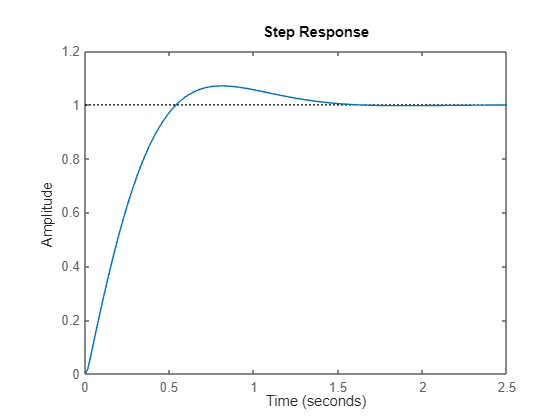

step(sys_cl)

si = stepinfo(sys_cl, "SettlingTimeThreshold", 0.05)

si = struct with fields:
         RiseTime: 0.3793
    TransientTime: 1.0466
     SettlingTime: 1.0466
      SettlingMin: 0.9066
      SettlingMax: 1.0704
        Overshoot: 7.0392
       Undershoot: 0
             Peak: 1.0704
         PeakTime: 0.8127


tau = si.SettlingTime/2

tau = 0.5233

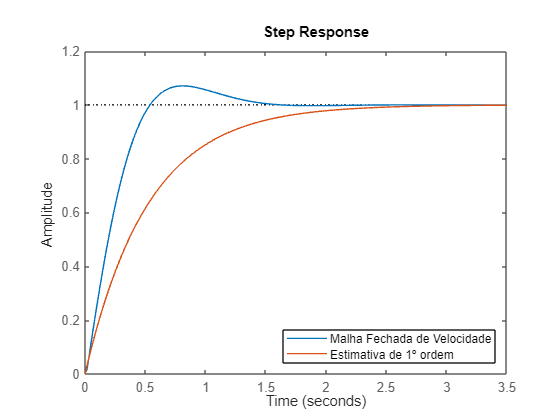

G_dx = 1/(tau*s+1);

figure
step(sys_cl, G_dx)
legend("Malha Fechada de Velocidade", "Estimativa de 1º ordem", "Location", "southeast")

## Controlador para Psi

psi_states = [3 6];
Apsi = An(psi_states,psi_states)

Apsi =          0    1.0000
         0   -7.7192


Bpsi = Bn(psi_states,2)

Bpsi =          0
  -17.3540


Cpsi = [1 0]

Cpsi =      1     0


sys_psi = ss(Apsi, Bpsi, Cpsi, 0)

sys_psi =
 
  A = 
           x1      x2
   x1       0       1
   x2       0  -7.719
 
  B = 
           u1
   x1       0
   x2  -17.35
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model 

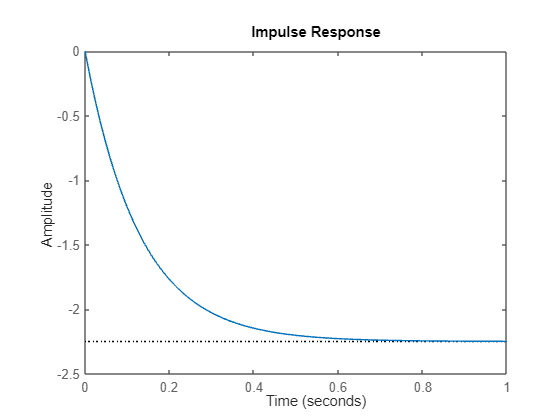

impulse(sys_psi)

G_psi = zpk(sys_psi)

G_psi =
 
    -17.354
  -----------
  s (s+7.719)
 
Continuous-time zero/pole/gain model.
Model Properties


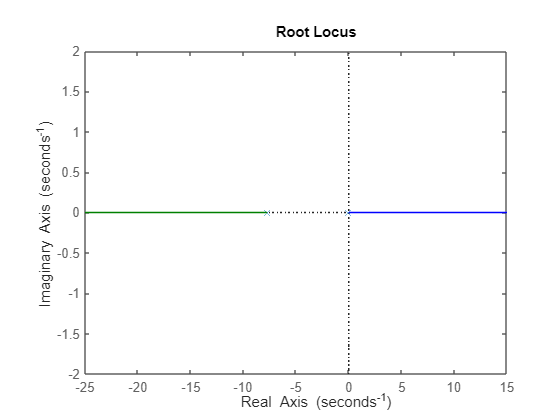

rlocus(G_psi)

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


C_psi = -3*(s+2)/s

C_psi =
 
  -3 s - 6
  --------
     s
 
Continuous-time transfer function.
Model Properties


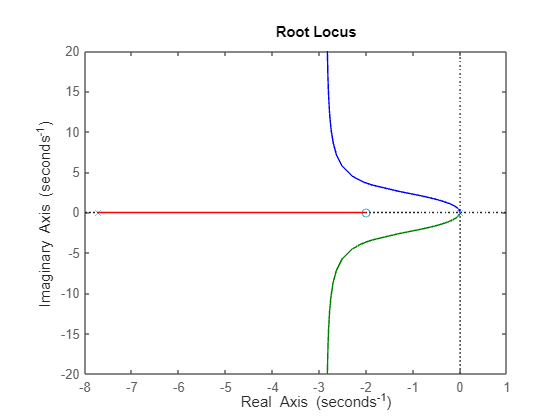

F_psi = 2/(s+2);
rlocus(C_psi*G_psi)

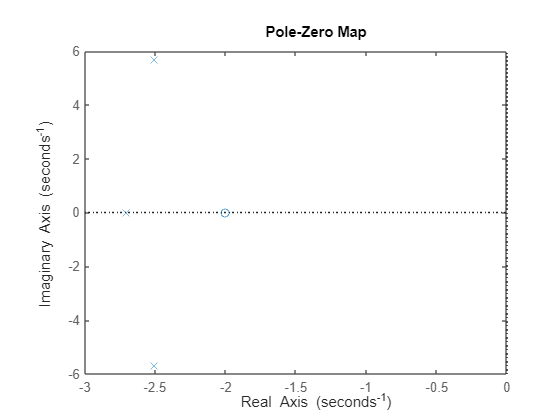

pzplot(feedback(C_psi*G_psi,1))

feedback(C_psi*G_psi,1)

ans =
 
           52.062 (s+2)
  -------------------------------
  (s+2.705) (s^2 + 5.015s + 38.5)
 
Continuous-time zero/pole/gain model.
Model Properties


G_psi_mf = F_psi*feedback(C_psi*G_psi,1)

G_psi_mf =
 
              104.12 (s+2)
  -------------------------------------
  (s+2) (s+2.705) (s^2 + 5.015s + 38.5)
 
Continuous-time zero/pole/gain model.
Model Properties


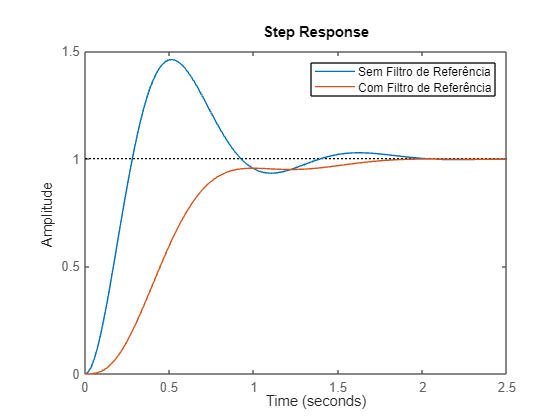

step(feedback(C_psi*G_psi,1), G_psi_mf)
legend("Sem Filtro de Referência", "Com Filtro de Referência")

stepinfo(G_psi_mf, "SettlingTimeThreshold", 0.05)

ans = struct with fields:
         RiseTime: 0.5473
    TransientTime: 1.2529
     SettlingTime: 1.2529
      SettlingMin: 0.9086
      SettlingMax: 0.9990
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9990
         PeakTime: 2.7367


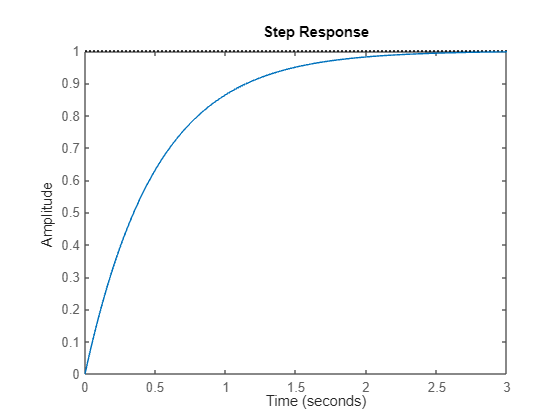

step(F_psi)

F_psi_d = c2d(F_psi, 0.005)

F_psi_d =
 
  0.00995
  --------
  z - 0.99
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


Nc = F_psi_d.Numerator{1};
Dc = F_psi_d.Denominator{1};
M = idpoly(Dc, Nc, 'NoiseVariance', 0)

M =
Discrete-time ARX model: A(z)y(t) = B(z)u(t)
  A(z) = 1 - 0.99 z^-1                      
                                            
  B(z) = 0.00995 z^-1                       
                                            
Sample time: unspecified
  
Parameterization:
   Polynomial orders:   na=1   nb=1   nk=1
   Number of free coefficients: 2
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                         
Created by direct construction or transformation. Not estimated.
 
Model Properties


M.A, M.B

ans =     1.0000   -0.9900


ans =          0    0.0100


## Outro Controlador para Psi

psi_states = [3 6];
Apsi = An(psi_states,psi_states)

Apsi =          0    1.0000
         0   -7.7192


Bpsi = Bn(psi_states,2)

Bpsi =          0
  -17.3540


Cpsi = [1 0]

Cpsi =      1     0


sys_psi = ss(Apsi, Bpsi, Cpsi, 0)

sys_psi =
 
  A = 
           x1      x2
   x1       0       1
   x2       0  -7.719
 
  B = 
           u1
   x1       0
   x2  -17.35
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model 

G_psi = zpk(sys_psi)

G_psi =
 
    -17.354
  -----------
  s (s+7.719)
 
Continuous-time zero/pole/gain model.
Model Properties


figure
impulse(sys_psi)

G_psi = zpk(sys_psi)

G_psi =
 
    -17.354
  -----------
  s (s+7.719)
 
Continuous-time zero/pole/gain model.
Model Properties


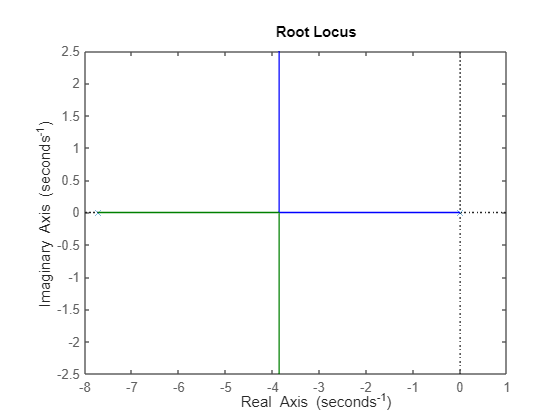

figure
rlocus(-G_psi)

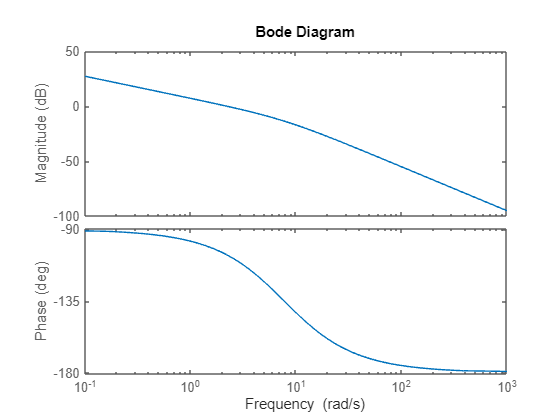

bode(-G_psi)

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


G_psi

G_psi =
 
    -17.354
  -----------
  s (s+7.719)
 
Continuous-time zero/pole/gain model.
Model Properties


x = 7.719;
K = 17.354;
zeta = 0.7;
wn = 4/(1.5*zeta)

wn = 3.8095

p = x - 2*zeta*wn

p = 2.3857

Kp = (wn^2 + 2*p*zeta*wn)/K

Kp = 1.5694

Ti = (K*Kp)/(p*wn^2)

Ti = 0.7867

C_psi = zpk(-Kp * (1 + 1/(Ti*s)))

C_psi =
 
  -1.5694 (s+1.271)
  -----------------
          s
 
Continuous-time zero/pole/gain model.
Model Properties


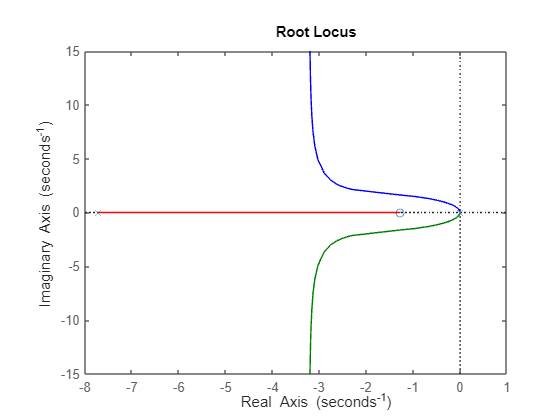

rlocus(C_psi*G_psi)

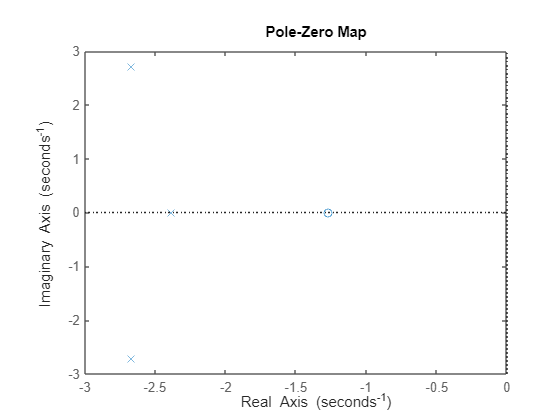

pzplot(feedback(C_psi*G_psi,1))

feedback(C_psi*G_psi,1)

ans =
 
          27.236 (s+1.271)
  --------------------------------
  (s+2.386) (s^2 + 5.333s + 14.51)
 
Continuous-time zero/pole/gain model.
Model Properties


F_psi = 1/(Ti*s+1)

F_psi =
 
       1
  ------------
  0.7867 s + 1
 
Continuous-time transfer function.
Model Properties


G_psi_mf = F_psi*feedback(C_psi*G_psi,1)

G_psi_mf =
 
               34.622 (s+1.271)
  ------------------------------------------
  (s+1.271) (s+2.386) (s^2 + 5.333s + 14.51)
 
Continuous-time zero/pole/gain model.
Model Properties


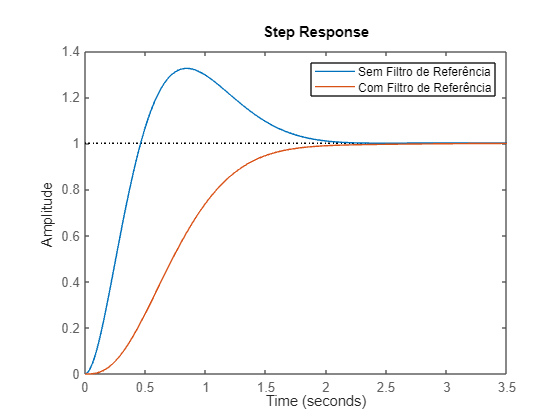

step(feedback(C_psi*G_psi,1), G_psi_mf)
legend("Sem Filtro de Referência", "Com Filtro de Referência")

stepinfo(G_psi_mf, "SettlingTimeThreshold", 0.05)

ans = struct with fields:
         RiseTime: 0.9946
    TransientTime: 1.5156
     SettlingTime: 1.5156
      SettlingMin: 0.9056
      SettlingMax: 0.9997
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9997
         PeakTime: 3.6481


F_psi_d = c2d(F_psi, 0.003)

F_psi_d =
 
   0.003806
  ----------
  z - 0.9962
 
Sample time: 0.003 seconds
Discrete-time transfer function.
Model Properties


Nc = F_psi_d.Numerator{1};
Dc = F_psi_d.Denominator{1};
M = idpoly(Dc, Nc, 'NoiseVariance', 0)

M =
Discrete-time ARX model: A(z)y(t) = B(z)u(t)
  A(z) = 1 - 0.9962 z^-1                    
                                            
  B(z) = 0.003806 z^-1                      
                                            
Sample time: unspecified
  
Parameterization:
   Polynomial orders:   na=1   nb=1   nk=1
   Number of free coefficients: 2
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                         
Created by direct construction or transformation. Not estimated.
 
Model Properties


M.A, M.B

ans =     1.0000   -0.9962


ans =          0    0.0038


% syms x Kp Ti x K zeta omega_n p
% syms s
% G_psi
% G = K/(s*(s+x))
% C = Kp*(1 + 1/(Ti*s))
% [N,D] = numden(1 + C*G)
% N = expand(N)
% Nd = (s+p)*(s^2 + 2*zeta*omega_n*s + omega_n^2);
% Nd = expand(Nd)
% eqn = N == Nd

## Dados Reais

dados_reais = readtable("dados_controle_real4.txt")

dados_reais = 200×9 table
     t         V       DeltaV     ref_dx    ref_psi      x         dx        theta       psi  
    ____    _______    _______    ______    _______    ______    _______    _______    _______

       0    -48.602          0      0          0       0.0065     1.0846    -0.0396          0
    0.15      0.025     0.0408      0          0       -0.001     0.0187     0.0022     0.0239
     0.3     16.638     0.0273      0          0       0.0052     0.0804       0.03      0.013
    0.45     10.681     0.0152      0          0       0.0324     0.1513    -0.0385     0.0046
     0.6    -3.0643     0.0295      0          0       0.0488    -0.0099    -0.0924     0.0113
  

dados_reais = dados_reais(dados_reais.t >= 5,:);
dados_reais.t = dados_reais.t - 5;

Ts = mean(diff(dados_reais.t))

Ts = 0.1501

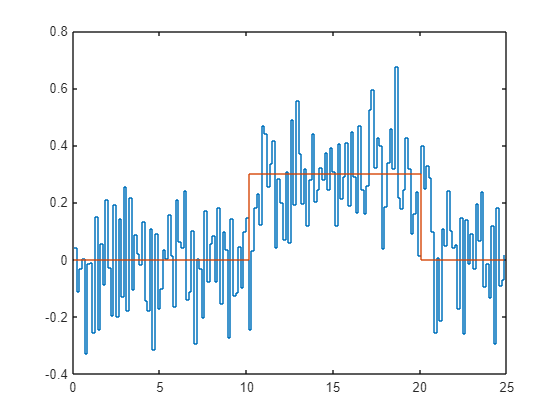

% dados_reais = dados_reais(1:30:end,:);

figure
stairs(dados_reais.t, smoothdata(dados_reais.dx, "movmedian", 1))
hold on
stairs(dados_reais.t, dados_reais.ref_dx)

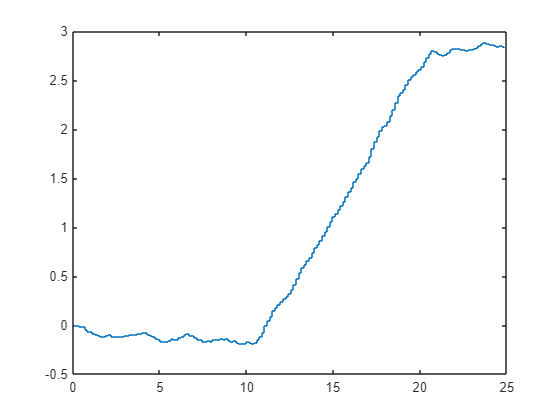

dados_reais.x = cumtrapz(dados_reais.t, dados_reais.dx);
figure
stairs(dados_reais.t, dados_reais.x)

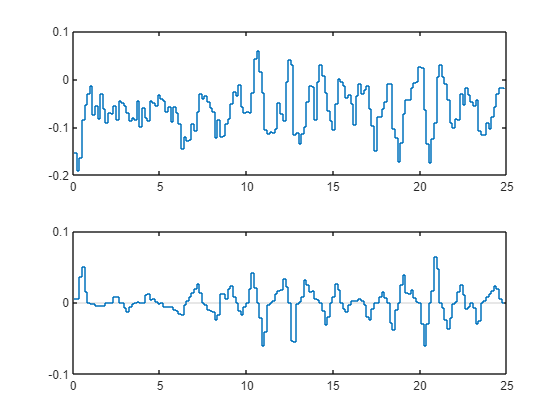

figure
subplot(2,1,1)
stairs(dados_reais.t, smoothdata(dados_reais.theta, "movmedian", 1))
ax = subplot(2,1,2);
stairs(dados_reais.t, gradient(smoothdata(dados_reais.theta, "movmedian", 5)))  
ax.YGrid = "on"; ylim([-0.1 0.1]), yticks([-0.1 0 0.1])

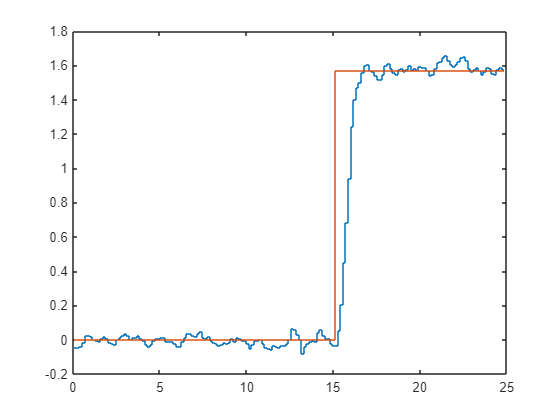

figure
stairs(dados_reais.t, smoothdata(dados_reais.psi, "movmedian", 1))
hold on
stairs(dados_reais.t, dados_reais.ref_psi)

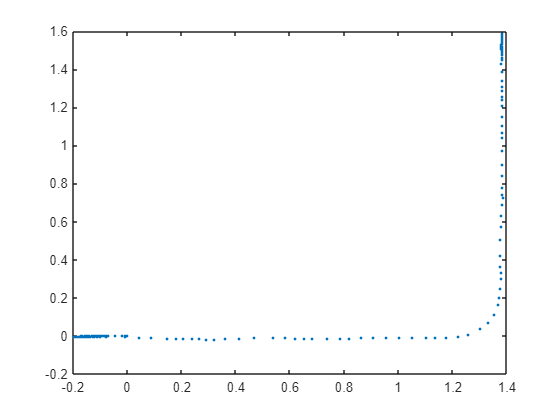

X = cumtrapz(dados_reais.t, cos(dados_reais.psi).*dados_reais.dx);
Y = cumtrapz(dados_reais.t, sin(dados_reais.psi).*dados_reais.dx);
figure
plot(X, Y, ".")

### Plot temporario

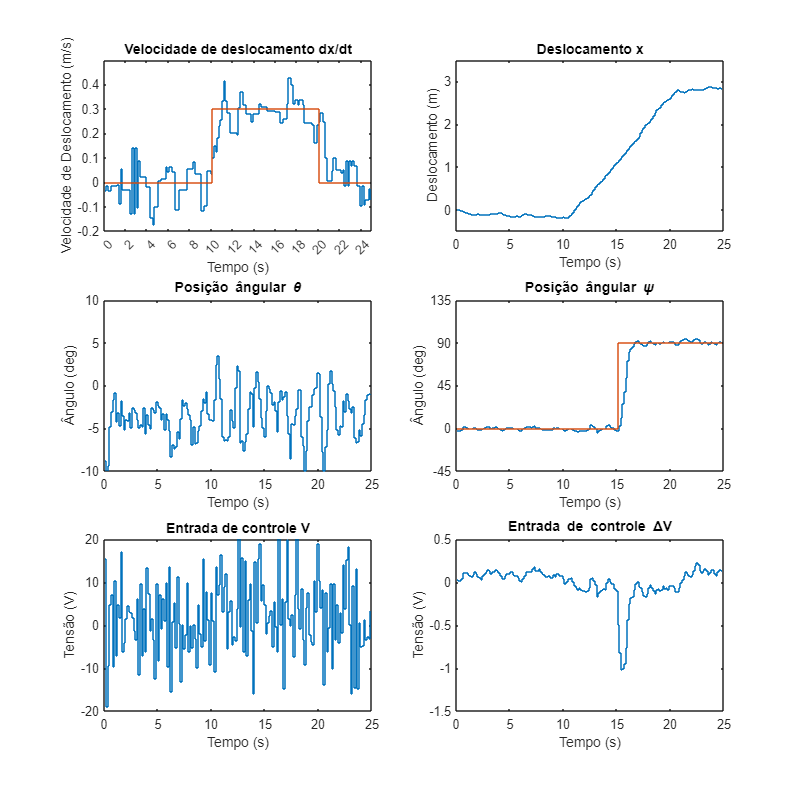

figure("Position", [0 0 1000 1000 * 3/3])
subplot(3,2,1)
stairs(dados_reais.t, smoothdata(dados_reais.dx, "movmedian", 5))
hold on
stairs(dados_reais.t, dados_reais.ref_dx)
title("Velocidade de deslocamento dx/dt")
xlabel("Tempo (s)"), ylabel("Velocidade de Deslocamento (m/s)"), xlim([0 25]), ylim([-0.2 0.5])
xticks(0:2:25)

subplot(3,2,3)
stairs(dados_reais.t, rad2deg(smoothdata(dados_reais.theta, "movmedian", 1)))
title("Posição ângular \theta")
xlabel("Tempo (s)"), ylabel("Ângulo (deg)"), ylim([-15 10]), xlim([0 25]), ylim([-10 10])

subplot(3,2,5)
stairs(dados_reais.t, smoothdata(dados_reais.V, "movmedian", 1))
title("Entrada de controle V")
xlabel("Tempo (s)"), ylabel("Tensão (V)"), xlim([0 25]), ylim([-20 20])

subplot(3,2,2)
stairs(dados_reais.t, dados_reais.x)
title("Deslocamento x")
xlabel("Tempo (s)"), ylabel("Deslocamento (m)"), xlim([0 25]), ylim([-0.5 3.5])
% scatter(X, Y, 3, dados_reais.t)
% title("Posição espacial X e Y")
% xlabel("Posição x (m)"), ylabel("Posição y (m)")
% ylim([-0.2 1.7])
% axis equal
% box on
% colororder("gem")

subplot(3,2,4)
stairs(dados_reais.t, rad2deg(smoothdata(dados_reais.psi, "movmedian", 1)))
hold on
stairs(dados_reais.t, rad2deg(dados_reais.ref_psi))
title("Posição ângular \psi")
xlabel("Tempo (s)"), ylabel("Ângulo (deg)"), ylim([-45 135]), yticks(-45:45:135), xlim([0 25])

subplot(3,2,6)
stairs(dados_reais.t, smoothdata(dados_reais.DeltaV, "movmedian", 1))
title("Entrada de controle \DeltaV")
xlabel("Tempo (s)"), ylabel("Tensão (V)"), xlim([0 25]), ylim([-1.5 0.5])

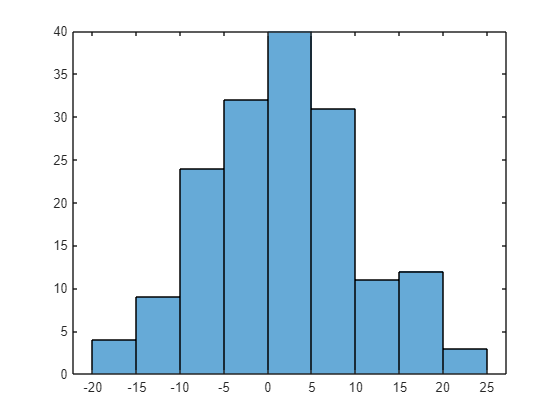

figure
histogram(dados_reais.V)

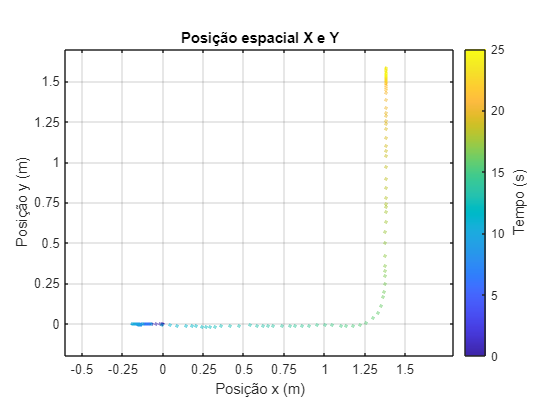

figure
scatter(X, Y, 3, dados_reais.t)
title("Posição espacial X e Y")
xlabel("Posição x (m)"), ylabel("Posição y (m)")
ylim([-0.2 1.7])
axis equal
box on
colororder("gem")
cb = colorbar;
ylabel(cb, "Tempo (s)", "FontSize", 11)
xticks(-1.5:0.25:1.5), yticks(-1.5:0.25:1.5), set(cb,'YTick',0:5:25), set(cb,'YLim',[0 25])
grid on

G_psi = tf(G_psi)

G_psi =
 
     -17.35
  -------------
  s^2 + 7.719 s
 
Continuous-time transfer function.
Model Properties


C_psi = tf(C_psi)

C_psi =
 
  -1.569 s - 1.995
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


out = sim("modelo8_simulink_controle_integral_doc.slx")

out =   Simulink.SimulationOutput:

                   tout: [3766x1 double] 
                   yout: [3766x14 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


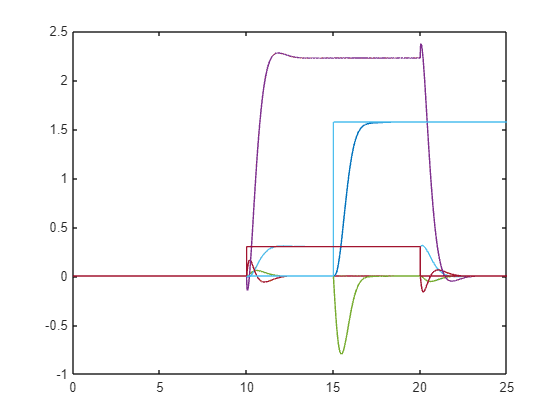

figure
plot(out.tout, out.yout)

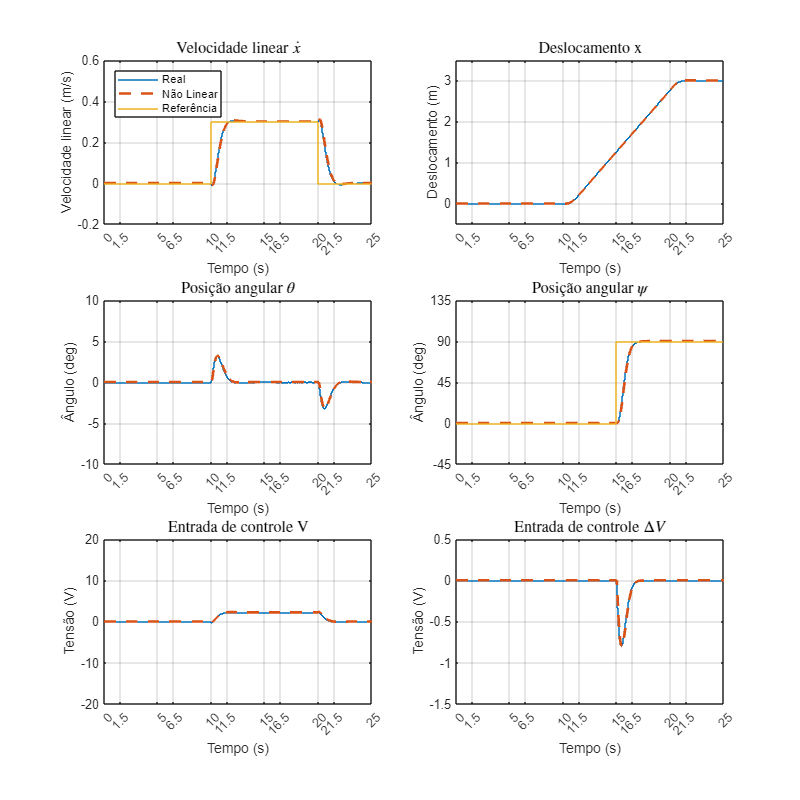

dados_reais = table();
dados_reais.t = out.tout;
dados_reais.theta = out.yout(:,1);
dados_reais.dx = out.yout(:,2);
dados_reais.psi = out.yout(:,4);
dados_reais.V = out.yout(:,9);
dados_reais.DeltaV = out.yout(:,10);
dados_reais.x = cumtrapz(dados_reais.t, dados_reais.dx);
dados_reais.ref_dx = out.yout(:,14);
dados_reais.ref_psi = out.yout(:,13);

dados_reais2 = table();
dados_reais2.t = out.tout;
dados_reais2.theta = out.yout(:,5);
dados_reais2.dx = out.yout(:,6);
dados_reais2.psi = out.yout(:,8);
dados_reais2.V = out.yout(:,11);
dados_reais2.DeltaV = out.yout(:,12);
dados_reais2.x = cumtrapz(dados_reais2.t, dados_reais2.dx);

xt = [0 1.5 5 6.5 10 11.5 15 16.5 20 21.5 25];

figure("Position", [0 0 1000 1000 * 3/3])
subplot(3,2,1)
stairs(dados_reais.t, smoothdata(dados_reais.dx, "movmedian", 5))
hold on
stairs(dados_reais2.t, dados_reais2.dx, "--", "LineWidth", 2)
stairs(dados_reais.t, dados_reais.ref_dx)
title("Velocidade linear $\dot{x}$",'interpreter','latex','FontSize',12)
xlabel("Tempo (s)"), ylabel("Velocidade linear (m/s)"), xlim([0 25]), ylim([-0.2 0.6])
xticks(xt)
grid on
legend("Real", "Não Linear", "Referência", "Location", "northwest")

subplot(3,2,3)
stairs(dados_reais.t, rad2deg(smoothdata(dados_reais.theta, "movmedian", 1)))
hold on 
stairs(dados_reais2.t, rad2deg(dados_reais2.theta), "--", "LineWidth", 2)
title("Posi\c{c}\~ao angular $\theta$",'interpreter','latex','FontSize',12)
xlabel("Tempo (s)"), ylabel("Ângulo (deg)"), ylim([-15 10]), xlim([0 25]), ylim([-10 10])
xticks(xt)
grid on

subplot(3,2,5)
stairs(dados_reais.t, smoothdata(dados_reais.V, "movmedian", 1))
hold on
stairs(dados_reais2.t, dados_reais2.V, "--", "LineWidth", 2)
title("Entrada de controle V",'interpreter','latex','FontSize',12)
xlabel("Tempo (s)"), ylabel("Tensão (V)"), xlim([0 25]), ylim([-20 20])
xticks(xt)
grid on

subplot(3,2,2)
stairs(dados_reais.t, dados_reais.x)
hold on
stairs(dados_reais2.t, dados_reais2.x, "--", "LineWidth", 2)
title("Deslocamento x",'interpreter','latex','FontSize',12)
xlabel("Tempo (s)"), ylabel("Deslocamento (m)"), xlim([0 25]), ylim([-0.5 3.5])
xticks(xt)
grid on

subplot(3,2,4)
stairs(dados_reais.t, rad2deg(smoothdata(dados_reais.psi, "movmedian", 1)))
hold on
stairs(dados_reais2.t, rad2deg(dados_reais2.psi), "--", "LineWidth", 2)
stairs(dados_reais.t, rad2deg(dados_reais.ref_psi))
title('Posi\c{c}\~ao angular $\psi$','interpreter','latex','FontSize',12)
xlabel("Tempo (s)"), ylabel("Ângulo (deg)"), ylim([-45 135]), yticks(-45:45:135), xlim([0 25])
xticks(xt)
grid on

subplot(3,2,6)
stairs(dados_reais.t, smoothdata(dados_reais.DeltaV, "movmedian", 1))
hold on
stairs(dados_reais2.t, dados_reais2.DeltaV, "--", "LineWidth", 2)
title("Entrada de controle $\Delta{V}$",'interpreter','latex','FontSize',12)
xlabel("Tempo (s)"), ylabel("Tensão (V)"), xlim([0 25]), ylim([-1.5 0.5])
xticks(xt)
grid on
saveas(gcf, "simulacao.png")


dados_reais2 = dados_reais;
dados_reais = readtable("dados_controle_real4.txt")

dados_reais = 200×9 table
     t         V       DeltaV     ref_dx    ref_psi      x         dx        theta       psi  
    ____    _______    _______    ______    _______    ______    _______    _______    _______

       0    -48.602          0      0          0       0.0065     1.0846    -0.0396          0
    0.15      0.025     0.0408      0          0       -0.001     0.0187     0.0022     0.0239
     0.3     16.638     0.0273      0          0       0.0052     0.0804       0.03      0.013
    0.45     10.681     0.0152      0          0       0.0324     0.1513    -0.0385     0.0046
     0.6    -3.0643     0.0295      0          0       0.0488    -0.0099    -0.0924     0.0113
  

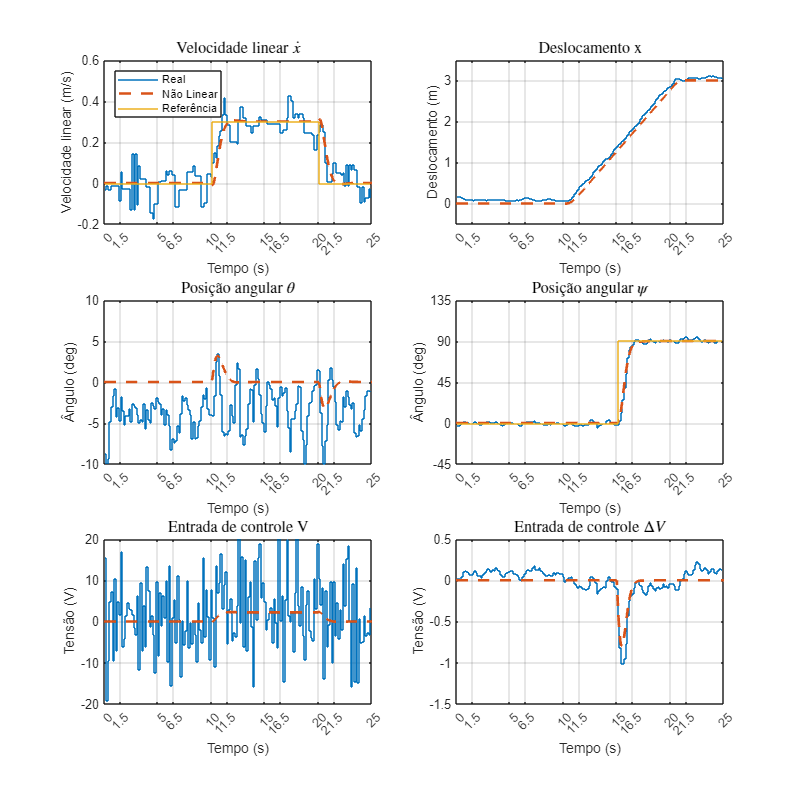

dados_reais = dados_reais(dados_reais.t >= 5,:);
dados_reais.t = dados_reais.t - 5;

figure("Position", [0 0 1000 1000 * 3/3])
subplot(3,2,1)
stairs(dados_reais.t, smoothdata(dados_reais.dx, "movmedian", 5))
hold on
stairs(dados_reais2.t, dados_reais2.dx, "--", "LineWidth", 2)
stairs(dados_reais.t, dados_reais.ref_dx)
title("Velocidade linear $\dot{x}$",'interpreter','latex','FontSize',12)
xlabel("Tempo (s)"), ylabel("Velocidade linear (m/s)"), xlim([0 25]), ylim([-0.2 0.6])
xticks(xt)
grid on
legend("Real", "Não Linear", "Referência", "Location", "northwest")

subplot(3,2,3)
stairs(dados_reais.t, rad2deg(smoothdata(dados_reais.theta, "movmedian", 1)))
hold on 
stairs(dados_reais2.t, rad2deg(dados_reais2.theta), "--", "LineWidth", 2)
title("Posi\c{c}\~ao angular $\theta$",'interpreter','latex','FontSize',12)
xlabel("Tempo (s)"), ylabel("Ângulo (deg)"), ylim([-15 10]), xlim([0 25]), ylim([-10 10])
xticks(xt)
grid on

subplot(3,2,5)
stairs(dados_reais.t, smoothdata(dados_reais.V, "movmedian", 1))
hold on
stairs(dados_reais2.t, dados_reais2.V, "--", "LineWidth", 2)
title("Entrada de controle V",'interpreter','latex','FontSize',12)
xlabel("Tempo (s)"), ylabel("Tensão (V)"), xlim([0 25]), ylim([-20 20])
xticks(xt)
grid on

subplot(3,2,2)
stairs(dados_reais.t, dados_reais.x)
hold on
stairs(dados_reais2.t, dados_reais2.x, "--", "LineWidth", 2)
title("Deslocamento x",'interpreter','latex','FontSize',12)
xlabel("Tempo (s)"), ylabel("Deslocamento (m)"), xlim([0 25]), ylim([-0.5 3.5])
xticks(xt)
grid on

subplot(3,2,4)
stairs(dados_reais.t, rad2deg(smoothdata(dados_reais.psi, "movmedian", 1)))
hold on
stairs(dados_reais2.t, rad2deg(dados_reais2.psi), "--", "LineWidth", 2)
stairs(dados_reais.t, rad2deg(dados_reais.ref_psi))
title('Posi\c{c}\~ao angular $\psi$','interpreter','latex','FontSize',12)
xlabel("Tempo (s)"), ylabel("Ângulo (deg)"), ylim([-45 135]), yticks(-45:45:135), xlim([0 25])
xticks(xt)
grid on

subplot(3,2,6)
stairs(dados_reais.t, smoothdata(dados_reais.DeltaV, "movmedian", 1))
hold on
stairs(dados_reais2.t, dados_reais2.DeltaV, "--", "LineWidth", 2)
title("Entrada de controle $\Delta{V}$",'interpreter','latex','FontSize',12)
xlabel("Tempo (s)"), ylabel("Tensão (V)"), xlim([0 25]), ylim([-1.5 0.5])
xticks(xt)
grid on

saveas(gcf, "real.png")